% do various score threshold and various pixel threshold


directory = 'FOVsFiltered';
files = dir(directory);

FOVs = {'1b_1', '1b_2', '1b_3', '1b_4', '1c_1', '1c_2', '1d_1', '2a_1', '2b_1', ...
    '2b_2', '3a_1', '3a_2', '3b_1', '3b_2', '3b_3', '3b_4', '3c_1', '3d_1', '3d_2', ...
    '4a_1', '4a_2', '4c_1', '4c_2', '4c_3', '4c_4', '5a_1', '5a_2', '5a_3', ...
    '5b_1', '5b_2', '5b_3', '5b_4', '5d_1'};

score_all = {};
precision_all = {};
recall_all = {};

score_threshold = [0.5, 0.55, 0.6, 0.65];
numberNeighboringPixels = 6;
for k = 1:4
    score_th = {};
    precision_th = {};
    recall_th = {};
    for i = 1:33
        %load rf_mirsi_score
        a = append(append('./FOVs/FOV_',FOVs(i)), '_score.mat');
        rf = load(a{1});
        rf = struct2cell(rf);
        rf = rf{1};
        %apply threshold
        rf = rf > score_threshold(k);
        %apply density filter
        rf_density = ( conv2(single(rf),ones(3),'same') >= numberNeighboringPixels ) & rf;
        %sprintf('k = %d i = %d',k, i)
        %access struct via index
        %https://www.mathworks.com/matlabcentral/answers/326938-how-to-access-a-field-of-a-struct-by-indexing
        a = load(append('./FOVsFiltered/',files(i+2).name));
        fns = fieldnames(a);
        score_px = [];
        precision_px = [];
        recall_px = [];
        for j = 1:8
            sprintf('k = %d i = %d j = %d', k, i, j)
            [score, precision, recall] = bfscore(rf_density, a.(fns{2}), j);
            score_px = [score_px, score];
            precision_px = [precision_px, precision];
            recall_px = [recall_px, recall];
        end
        
        score_th{end + 1} = score_px;
        precision_th{end + 1} = precision_px;
        recall_th{end + 1} = recall_px;
    
    end
    score_all{end + 1} = score_th;
    precision_all{end + 1} = precision_th;
    recall_all{end + 1} = recall_th;
end



score = {};

for i = 1:4
    a = score_all{i};
    score_b = [];
    for j=1:33
        score_b = [score_b, a{j}.'];
    end

    score{end+1} = score_b; 

end

score_1 = score{1};
score_1 = mean(score_1,2);
score_2 = score{2};
score_2 = mean(score_2,2);
score_3 = score{3};
score_3 = mean(score_3,2);
score_4 = score{4};
score_4 = mean(score_4,2);

score_1_std = score{1};
score_1_std = std(score_1_std,0,2);
score_2_std = score{2};
score_2_std = std(score_2_std,0,2);
score_3_std = score{3};
score_3_std = std(score_3_std,0,2);
score_4_std = score{4};
score_4_std = std(score_4_std,0,2);

score = [score_1, score_2, score_3, score_4];
imagesc([0.5, 0.55, 0.6, 0.65].*100,1:8,score)
xticks([0.5, 0.55, 0.6, 0.65].*100)
xlabel("Collagen probability threshold [%]")
ylabel("Boundary F-score threshold [px]")
title("Boundary F-score")

plot(score_1)
hold on
plot(score_2)
plot(score_3)
plot(score_4)
xlabel("Boundary F-score threshold [px]")
ylabel("Boundary F-score")
legend(["50%","55%","60%","65%"])
set(findall(gcf,'-property','FontSize'),'FontSize',13)
title("Average boundary F-score vs pixel threshold")

plot(score_1, 'Color',[0 0.4470 0.7410])
hold on 
curve1 = score_1 + score_1_std;
curve2 = score_1 - score_1_std;
x2 = [1:8, fliplr(1:8)];
inBetween = [curve1; flipud(curve2)].';
fill(x2, inBetween, [0 0.4470 0.7410],'FaceAlpha',0.3, 'HandleVisibility','off')

plot(score_2, 'Color',[0.8500 0.3250 0.0980])

curve1 = score_2 + score_2_std;
curve2 = score_2 - score_2_std;
x2 = [1:8, fliplr(1:8)];
inBetween = [curve1; flipud(curve2)].';
fill(x2, inBetween, [0.8500 0.3250 0.0980],'FaceAlpha',0.3, 'HandleVisibility','off')


plot(score_3, 'Color',[0.4660 0.6740 0.1880])

curve1 = score_3 + score_3_std;
curve2 = score_3 - score_3_std;
x2 = [1:8, fliplr(1:8)];
inBetween = [curve1; flipud(curve2)].';
fill(x2, inBetween, [0.4660 0.6740 0.1880],'FaceAlpha',0.3, 'HandleVisibility','off')

plot(score_4, 'Color',[0.6350 0.0780 0.1840])

curve1 = score_4 + score_4_std;
curve2 = score_4 - score_4_std;
x2 = [1:8, fliplr(1:8)];
inBetween = [curve1; flipud(curve2)].';
fill(x2, inBetween, [0.6350 0.0780 0.1840],'FaceAlpha',0.3, 'HandleVisibility','off')



xlabel("Boundary F-score threshold [px]")
ylabel("Boundary F-score")
legend(["50%","55%","60%","65%"])
set(findall(gcf,'-property','FontSize'),'FontSize',13)
title("Average boundary F-score vs pixel threshold")

%scatter(1:8, score_1, 'MarkerFaceColor',[0 0.4470 0.7410],'HandleVisibility','off')
%hold on
plot(score_1, 'Color',[0 0.4470 0.7410])
hold on
eb(1) = errorbar(1:8,score_1,score_1_std, 'vertical', 'LineStyle', 'none', 'HandleVisibility','off');

%scatter(1:8, score_2, 'MarkerFaceColor',[0.8500 0.3250 0.0980],'HandleVisibility','off')
plot(score_2, 'Color',[0.8500 0.3250 0.0980])
eb(2) = errorbar(1:8,score_2,score_2_std, 'vertical', 'LineStyle', 'none', 'HandleVisibility','off');

%scatter(1:8, score_3, 'MarkerFaceColor',[0.4660 0.6740 0.1880],'HandleVisibility','off')
plot(score_3, 'Color',[0.4660 0.6740 0.1880])
eb(3) = errorbar(1:8,score_3,score_3_std, 'vertical', 'LineStyle', 'none', 'HandleVisibility','off');

%scatter(1:8, score_4, 'MarkerFaceColor',[0.6350 0.0780 0.1840],'HandleVisibility','off')
plot(score_4, 'Color',[0.6350 0.0780 0.1840])
eb(4) = errorbar(1:8,score_4,score_4_std, 'vertical', 'LineStyle', 'none', 'HandleVisibility','off');

set(eb(1), 'color', [0 0.4470 0.7410], 'LineWidth', 0.5)
set(eb(2), 'color', [0.8500 0.3250 0.0980], 'LineWidth', 0.5)
set(eb(3), 'color', [0.4660 0.6740 0.1880], 'LineWidth', 0.5)
set(eb(4), 'color', [0.6350 0.0780 0.1840], 'LineWidth', 0.5)

xlabel("Boundary F-score threshold [px]")
ylabel("Boundary F-score")
legend(["50%","55%","60%","65%"])
set(findall(gcf,'-property','FontSize'),'FontSize',13)
title("Average boundary F-score vs pixel threshold")



%get bf1 score for all images
directory = 'FOVsFiltered';
files = dir(directory);


score_all = {};
precision_all = {};
recall_all = {};


for i = 3:33
    %access struct via index
    %https://www.mathworks.com/matlabcentral/answers/326938-how-to-access-a-field-of-a-struct-by-indexing
    a = load(append('./FOVsFiltered/',files(i).name));
    fns = fieldnames(a);
    [score, precision, recall] = bfscore(a.(fns{1}), a.(fns{2}), 8);
    score_all{end + 1} = score;
    precision_all{end + 1} = precision;
    recall_all{end + 1} = recall;

end

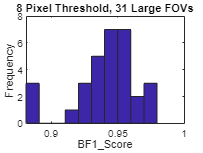

histogram(cell2mat(score_all), 5)
xlabel("BF1\_Score")
title("5 Pixel Threshold, 31 Large FOVs")
ylabel("# FOVs")

%get cosine distances for all images
directory = 'FOVsFiltered';
files = dir(directory);


similarity_all = {};


for i = 3:33
    %access struct via index
    %https://www.mathworks.com/matlabcentral/answers/326938-how-to-access-a-field-of-a-struct-by-indexing
    a = load(append('./FOVsFiltered/',files(i).name));
    fns = fieldnames(a);
    rf_mirsi = double(a.(fns{1}));
    shg = double(a.(fns{2}));
    %https://stackoverflow.com/questions/22432673/how-to-measure-the-cosine-similarity-between-2-images
    similarity = 1 - (dot(rf_mirsi(:), shg(:))./ (norm(rf_mirsi(:)) .* norm(shg(:))));
    
    similarity_all{end + 1} = similarity;

end

hist(cell2mat(similarity_all))
xlabel("Cosine Similarity")
ylabel("Frequency")

%structural similarity https://www.mathworks.com/help/images/ref/ssim.html
directory = 'FOVsFiltered';
files = dir(directory);


ssimval_all = {};
ssimmap_all = {};


for i = 3:33
    %access struct via index
    %https://www.mathworks.com/matlabcentral/answers/326938-how-to-access-a-field-of-a-struct-by-indexing
    a = load(append('./FOVsFiltered/',files(i).name));
    fns = fieldnames(a);
    rf_mirsi = double(a.(fns{1}));
    shg = double(a.(fns{2}));
    [ssimval,ssimmap] = ssim(rf_mirsi,shg);
    ssimval_all{end + 1} = ssimval;
    ssimmap_all{end + 1} = ssimmap;

end

hist(cell2mat(ssimval_all))
xlabel("SSim Val")
ylabel("Frequency")
title("Closer to 1 Means Good Similarity")


%imwrite(RF_MIRSI_FOV_5d_1_Filtered, 'RF_MIRSI_FOV_5d_1_Filtered.tiff', 'Compression', 'none' )
%imwrite(SHG_FOV_1b_4_Filtered, 'SHG_FOV_1b_4_Filtered.tiff', 'Compression', 'none' )

SHG_angles = [77.15, -70.30, 50.5, 72.81, 46.48, 89.61, 63.27, 18.00, ...
    -81.38, -34.80, 24.33, 33.83, -77.77, 87.99, 72.22, -42.60, ...
    -53.67, 47.24, 19.26, -5.35, 27.24, 60.51, -52.11, ...
    67.58, -17.31, -32.75, -1.19, -19.95, -0.147, 5.85, 20.64, -0.76, ...
    -59.10];

RF_MIRSI_angles = [-89.84, -60.84, 50.66, 77.87, -53.04, -86.90, 87.48, -6.00, ...
    -6.00, -80.45, -34.86, 25.58, 34.74, -58.64, -84.48, -83.48, -45.02, ...
    -53.47, 24.39, -18.82, 13.78, 65.65, -67.92, -77.10, -59.39, -36.86, -19.88,...
    -32.06, 87.87, 20.00, 44.60, 15.30, -60.29];

RF_MIRSI_score_angles = [60.60, -78.91, 42.11, 78.01, 59.22, 89.77, 76.22,...
    -1.55, -81.94, -39.30, 27.34, 37.85, -63.50, -81.26, -88.32, -31.36, ...
    -48.76, 49.96, 18.85, -17.78, 87.06, 65.63, -70.72, -83.85, -54.20, ...
    -33.46, -18.54, -30.01, -68.05, 13.53, 47.52, 10.90, -66.89];

angles_diff = SHG_angles - RF_MIRSI_angles;
angles_avg = (SHG_angles + RF_MIRSI_angles) ./2;
scatter(angles_avg, angles_diff)
hold on
xlabel("Angles Average of SHG and RF\_MIRSI [Degrees]")
ylabel("Angle Difference")
yline(mean(angles_diff),'b-')
yline(mean(angles_diff) + std(angles_diff),'r--')
yline(mean(angles_diff) - std(angles_diff),'r--')

angles_diff = SHG_angles - RF_MIRSI_score_angles;
angles_avg = (SHG_angles + RF_MIRSI_score_angles) ./2;
scatter(angles_avg, angles_diff)
hold on
xlabel("Angles Average of SHG and RF\_MIRSI\_Score [Degrees]")
ylabel("Angle Difference")
yline(mean(angles_diff),'b-')
yline(mean(angles_diff) + std(angles_diff),'r--')
yline(mean(angles_diff) - std(angles_diff),'r--')

abs_angles_diff = abs(SHG_angles) - abs(RF_MIRSI_angles);
abs_angles_avg = (abs(SHG_angles) + abs(RF_MIRSI_angles)) ./2;
scatter(abs_angles_avg, abs_angles_diff)
hold on
xlabel("Absolute Angles Average of SHG and RF\_MIRSI [Degrees]")
ylabel("Absolute Angle Difference")
yline(mean(abs_angles_diff),'b-')
yline(mean(abs_angles_diff) + std(abs_angles_diff),'r--')
yline(mean(abs_angles_diff) - std(abs_angles_diff),'r--')

abs_angles_diff = abs(SHG_angles) - abs(RF_MIRSI_score_angles);
abs_angles_avg = (abs(SHG_angles) + abs(RF_MIRSI_score_angles)) ./2;
scatter(abs_angles_avg, abs_angles_diff)
hold on
xlabel("Absolute Angles Average of SHG and RF\_MIRSI\_Score [Degrees]")
ylabel("Absolute Angle Difference")
yline(mean(abs_angles_diff),'b-')
yline(mean(abs_angles_diff) + std(abs_angles_diff),'r--')
yline(mean(abs_angles_diff) - std(abs_angles_diff),'r--')


FOVs = {'1b_1', '1b_2', '1b_3', '1b_4', '1c_1', '1c_2', '1d_1', '2a_1', '2b_1', ...
    '2b_2', '3a_1', '3a_2', '3b_1', '3b_2', '3b_3', '3b_4', '3c_1', '3d_1', '3d_2', ...
    '4a_1', '4a_2', '4c_1', '4c_2', '4c_3', '4c_4', '5a_1', '5a_2', '5a_3', ...
    '5b_1', '5b_2', '5b_3', '5b_4', '5d_1'};

coord = combvec([1, 480, 960], [1, 480, 960]);

angle_RF_MIRSI_score_small = [];
angle_RF_MIRSI_small = [];
angle_SHG_small = [];
angle_SHG_small_2 = [];
coherence_RF_MIRSI_score_small = [];
coherence_RF_MIRSI_small = [];
coherence_SHG_small = [];
coherence_SHG_small_2 = [];

%loop over FOVs
for i = 1:33
    %counter for small FOVs, do 9 smaller FOVs for each FOV
    counter = 1;
    for j=1:9
        %read txt file
        %https://www.mathworks.com/matlabcentral/answers/230169-read-text-file-into-matlab
        %load txt file, not sure why ImageJ added .tiff to the end of the
        %file name
        shg = importdata(append('SHG_Filtered_Tiff_Small\', sprintf(append(FOVs{i}, '_%d.tiff.txt'), counter)));
        angle_SHG_small = [angle_SHG_small, shg.data(2)];
        coherence_SHG_small = [coherence_SHG_small, shg.data(3)];
        shg_2 = importdata(append('SHG_Tiff_Small\', sprintf(append(FOVs{i}, '_%d.tiff.txt'), counter)));
        angle_SHG_small_2 = [angle_SHG_small_2, shg_2.data(2)];
        coherence_SHG_small_2 = [coherence_SHG_small_2, shg_2.data(3)];
        rf_mirsi_score_small = importdata(append('RF_MIRSI_Score_Tiff_Small\', sprintf(append(FOVs{i}, '_%d.tiff.txt'), counter)));
        angle_RF_MIRSI_score_small = [angle_RF_MIRSI_score_small, rf_mirsi_score_small.data(2)];
        coherence_RF_MIRSI_score_small = [coherence_RF_MIRSI_score_small, rf_mirsi_score_small.data(3)];
        rf_mirsi_small = importdata(append('RF_MIRSI_Filtered_Tiff_Small\', sprintf(append(FOVs{i}, '_%d.tiff.txt'), counter)));
        angle_RF_MIRSI_small = [angle_RF_MIRSI_small, rf_mirsi_small.data(2)];
        coherence_RF_MIRSI_small = [coherence_RF_MIRSI_small, rf_mirsi_small.data(3)];
        
        
        counter = counter + 1;
    end
    %reset counter
    counter = 1;

end

angles_diff = angle_SHG_small - angle_RF_MIRSI_score_small;
angles_avg = (angle_SHG_small + angle_RF_MIRSI_score_small) ./2;
scatter(angles_avg, angles_diff)
hold on
xlabel("Angles Average of SHG and RF\_MIRSI\_Score [Degrees]")
ylabel("Angle Difference")
title("Small FOVs 480x480")
yline(mean(angles_diff),'b-')
yline(mean(angles_diff) + std(angles_diff),'r--')
yline(mean(angles_diff) - std(angles_diff),'r--')

angles_diff_2 = abs(angle_SHG_small) - abs(angle_RF_MIRSI_small);
angles_avg_2 = (abs(angle_SHG_small) + abs(angle_RF_MIRSI_small)) ./2;
scatter(angles_avg_2, angles_diff_2)
hold on
xlabel("Angles Average of SHG and RF\_MIRSI [Degrees]")
ylabel("Angle Difference")
title("Small FOVs 480x480")
yline(mean(angles_diff_2),'b-')
yline(mean(angles_diff_2) + std(angles_diff_2),'r--')
yline(mean(angles_diff_2) - std(angles_diff_2),'r--')

angles_diff_3 = abs(angle_SHG_small_2) - abs(angle_RF_MIRSI_small);
angles_avg_3 = (abs(angle_SHG_small_2) + abs(angle_RF_MIRSI_small)) ./2;
scatter(angles_avg_3, angles_diff_3)
hold on
xlabel("Angles Average of SHG and RF\_MIRSI [Degrees]")
ylabel("Angle Difference")
title("Small FOVs 480x480")
yline(mean(angles_diff_3),'b-')
yline(mean(angles_diff_3) + std(angles_diff_3),'r--')
yline(mean(angles_diff_3) - std(angles_diff_3),'r--')

hist(angles_diff, 30)
xlabel("Angle Difference [Degrees]")
ylabel("Counts")
title("RF MIRSI Score vs SHG Angles Dominant Direction 480x480")

hist(angles_diff_2, 30)
xlabel("Angle Difference [Degrees]")
ylabel("Counts")
title("RF MIRSI vs SHG Angles Dominant Direction 480x480")

hist(angles_diff_3, 30)
xlabel("Angle Difference [Degrees]")
ylabel("Counts")
title("RF MIRSI vs SHG Angles Dominant Direction 480x480")

angles_diff = abs(angle_SHG_small) - abs(angle_RF_MIRSI_score_small);
angles_avg = (abs(angle_SHG_small) + abs(angle_RF_MIRSI_score_small)) ./2;
scatter(angles_avg, angles_diff)
hold on
xlabel("Absolute Angles Average of SHG and RF\_MIRSI\_Score [Degrees]")
ylabel("Absolute Angle Difference")
title("Small FOVs 480x480")
yline(mean(angles_diff),'b-')
yline(mean(angles_diff) + std(angles_diff),'r--')
yline(mean(angles_diff) - std(angles_diff),'r--')

hist(angles_diff, 20)
xlabel("Absolute Angle Difference [Degrees]")
ylabel("Counts")
title("RF MIRSI Score vs SHG Angles Dominant Direction 480x480")

cosine_diff = cosd(angle_SHG_small) - cosd(angle_RF_MIRSI_score_small);
cosine_avg = (cosd(angle_SHG_small) + cosd(angle_RF_MIRSI_score_small)) ./2;
scatter(cosine_avg, cosine_diff)
hold on
xlabel("Average of Cosine of Angles of SHG and RF\_MIRSI\_Score [a.u.]")
ylabel("Difference of Cosine of Angles of SHG and RF\_MIRSI\_Score [a.u.]")
title("Small FOVs 480x480")
yline(mean(cosine_diff),'b-')
yline(mean(cosine_diff) + std(cosine_diff),'r--')
yline(mean(cosine_diff) - std(cosine_diff),'r--')

hist(cosine_diff, 30)
xlabel("Cosine Difference [Degrees]")
ylabel("Counts")
title("RF MIRSI Score vs SHG Angles Dominant Direction 480x480")

%pearson correlation angle
shg = abs(angle_SHG_small);
mirsi = abs(angle_RF_MIRSI_score_small);
A = [shg.', mirsi.'];
R = corrcoef(A)
scatter(shg, mirsi, "HandleVisibility","off")
xlabel("SHG global orientation [Degrees]")
ylabel("RF-MIRSI global orientation [Degrees]")
c = polyfit(shg, mirsi, 1);
hold on
plot(0:0.1:90, polyval(c, 0:0.1:90), 'Color', 'k')
lgd = legend("Pearson's R 0.78")
lgd.FontSize = 14;

%pearson correlation coherency
shg = coherence_SHG_small_2;
mirsi = coherence_RF_MIRSI_small;
A = [shg.', mirsi.'];
R = corrcoef(A)
scatter(shg, mirsi, "HandleVisibility","off")
xlabel("SHG coherency [%]")
ylabel("RF-MIRSI coherency [%]")
c = polyfit(shg, mirsi, 1);
hold on
plot(0:0.01:0.45, polyval(c, 0:0.01:0.45), 'Color', 'k')
lgd = legend("Pearson's R 0.47")
lgd.FontSize = 14;

figure()
A = [coherence_SHG_small.', coherence_RF_MIRSI_score_small.'];
R = corrcoef(A)
scatter(coherence_SHG_small, coherence_RF_MIRSI_score_small, "HandleVisibility","off")
xlabel("SHG coherence [%]")
ylabel("RF-MIRSI score coherence [%]")
c = polyfit(coherence_SHG_small, coherence_RF_MIRSI_score_small, 1);
hold on
plot(0:0.001:0.18, polyval(c, 0:0.001:0.18), 'Color', 'k')

figure()
A = [coherence_SHG_small_2.', coherence_RF_MIRSI_score_small.'];
R = corrcoef(A)
scatter(coherence_SHG_small_2, coherence_RF_MIRSI_score_small, "HandleVisibility","off")
xlabel("SHG coherence [%]")
ylabel("RF-MIRSI score coherence [%]")
c = polyfit(coherence_SHG_small_2, coherence_RF_MIRSI_score_small, 1);
hold on
plot(0:0.001:0.45, polyval(c, 0:0.001:0.45), 'Color', 'k')

figure()
A = [coherence_SHG_small.', coherence_RF_MIRSI_small.'];
R = corrcoef(A)
scatter(coherence_SHG_small, coherence_RF_MIRSI_small, "HandleVisibility","off")
xlabel("SHG coherency [%]")
ylabel("RF-MIRSI coherency [%]")
c = polyfit(coherence_SHG_small, coherence_RF_MIRSI_small, 1);
hold on
plot(0:0.001:0.18, polyval(c, 0:0.001:0.18), 'Color', 'k')
ylim([0, 0.15])

figure()
A = [coherence_SHG_small_2.', coherence_RF_MIRSI_small.'];
R = corrcoef(A)
scatter(coherence_SHG_small_2, coherence_RF_MIRSI_small, "HandleVisibility","off")
xlabel("SHG coherency [%]")
ylabel("RF-MIRSI coherency [%]")
c = polyfit(coherence_SHG_small_2, coherence_RF_MIRSI_small, 1);
hold on
plot(0:0.001:0.4, polyval(c, 0:0.001:0.4), 'Color', 'k')
ylim([0, 0.15])

[out_c,idx_c] = sort(abs(coherence_SHG_small - coherence_RF_MIRSI_small));
[out_d,idx_d] = sort(abs(abs(angle_SHG_small) - abs(angle_RF_MIRSI_small)));
[idx_c.', idx_d.'];